clear all;
% idqpref to idqp 的传递函数矩阵;
s= tf('s');
% syms idpref iqpref idp iqp idp1 iqp1 real

% 参数定义
Lfg = 1e-3; % Lfg = 1.75e-3;
Lfc = 3.75e-3;
Lf = Lfg + Lfc;
Cf = 20e-6;
Lg = 3.5e-3;
Rg = 0.5498 * 2;
omega0 = 100 * pi;

k = 0.707;
num = k*omega0*s^3+ k^2*omega0^2*s^2 +4*k*omega0^3*s +2*k^2*omega0^4;
den = 2*s^4+  4*k*omega0*s^3+  (2*k^2*omega0^2+8*omega0^2)*s^2 + 8*k*omega0^3*s + 2*k^2*omega0^4;

H_11n = num/den;
H_22n = H_11n;
num3 = k^2*omega0^3*s;
H_12n = num3/den;
H_21n = -1*H_12n;
HDQ_n =[H_11n H_12n;H_21n H_22n]; % HDQp
HDQ_n = minreal(HDQ_n);
H_11p = H_11n;
H_22p = H_11p;
H_12p = -H_12n;
H_21p = -1*H_12p;
HDQ_p =[H_11p H_12p;H_21p H_22p]; % HDQn
HDQ_p = minreal(HDQ_p);

## 控制部分

$\[{G_{pi}} = \left[ {\begin{array}{*{20}{c}}
{{k_p} + {k_i}/s}&0\\
0&{{k_p} + {k_i}/s}
\end{array}} \right],{G_{decouple}} = \left[ {\begin{array}{*{20}{c}}
0&{ - {\omega _0}{L_f}}\\
{{\omega _0}{L_f}}&0
\end{array}} \right]\]$，Lf是总滤波电感（Lfc+Lfg）

时延环节，时延1.5个周期，采用二阶pade近似。时延环节后的信号记为输出电压调制信号 v_m（modulation）

kp = 10;
ki = 250;
% kp = 10;
% ki = 400;
% PI 控制器
G_pi = [kp + ki/s, 0;
        0, kp + ki/s];
% 解耦项 G_decouple
G_decouple = [0, -omega0 * Lf;
         omega0 * Lf, 0];
% 时延
f_sw=10e3; T_sw=1/f_sw;
Tdelay=1.5*T_sw; 
G_delay = tf(1,1,'InputDelay',Tdelay);       % 含有 delay 的TF
G_delay_pade = pade(G_delay, 2);

## LCL正序，负序

$% MathType!MTEF!2!1!+-
% feaahqart1ev3aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBaerbd9wDYLwzYbItLDharqqtubsr
% 4rNCHbWexLMBbXgBd9gzLbvyNv2CaeHbl7mZLdGeaGqipu0Je9sqqr
% pepC0xbbL8F4rqqrFfpeea0xe9Lq-Jc9vqaqpepm0xbba9pwe9Q8fs
% 0-yqaqpepae9pg0FirpepeKkFr0xfr-xfr-xb9adbaqaaeGaciGaai
% aabeqaamaabaabauaakqGabeqaaqafbaacbmGaa8NwamaaBaaaleaa
% caWGmbGaamOzaiaadogaaeqaaOGaeyypa0ZaamWaaeaafaqabeGaca
% aabaGaam4CaiaadYeadaWgaaWcbaGaamOzaiaadogaaeqaaaGcbaGa
% eyOeI0IaeqyYdC3aaSbaaSqaaiaaicdaaeqaaOGaamitamaaBaaale
% aacaWGMbGaam4yaaqabaaakeaacqaHjpWDdaWgaaWcbaGaaGimaaqa
% baGccaWGmbWaaSbaaSqaaiaadAgacaWGJbaabeaaaOqaaiaadohaca
% WGmbWaaSbaaSqaaiaadAgacaWGJbaabeaaaaaakiaawUfacaGLDbaa
% caGGSaGaa8NwamaaBaaaleaacaWGdbGaamOzaaqabaGccqGH9aqpda
% WadaqaauaabeqaciaaaeaacaWGZbGaam4qamaaBaaaleaacaWGMbaa
% beaaaOqaaiabgkHiTiabeM8a3naaBaaaleaacaaIWaaabeaakiaado
% eadaWgaaWcbaGaamOzaaqabaaakeaacqaHjpWDdaWgaaWcbaGaaGim
% aaqabaGccaWGdbWaaSbaaSqaaiaadAgaaeqaaaGcbaGaam4Caiaado
% eadaWgaaWcbaGaamOzaaqabaaaaaGccaGLBbGaayzxaaWaaWbaaSqa
% beaacqGHsislcaaIXaaaaOGaaiilaaqaaiaa-PfadaWgaaWcbaGaam
% itaiaadAgacaWGNbaabeaakiabg2da9maadmaabaqbaeqabiGaaaqa
% aiaadohacaWGmbWaaSbaaSqaaiaadAgacaWGNbaabeaaaOqaaiabgk
% HiTiabeM8a3naaBaaaleaacaaIWaaabeaakiaadYeadaWgaaWcbaGa
% amOzaiaadEgaaeqaaaGcbaGaeqyYdC3aaSbaaSqaaiaaicdaaeqaaO
% GaamitamaaBaaaleaacaWGMbGaam4zaaqabaaakeaacaWGZbGaamit
% amaaBaaaleaacaWGMbGaam4zaaqabaaaaaGccaGLBbGaayzxaaGaai
% ilaiaa-PfadaWgaaWcbaGaam4zaaqabaGccqGH9aqpdaWadaqaauaa
% beqaciaaaeaacaWGZbGaamitamaaBaaaleaacaWGNbaabeaakiabgU
% caRiaadkfadaWgaaWcbaGaam4zaaqabaaakeaacqGHsislcqaHjpWD
% daWgaaWcbaGaaGimaaqabaGccaWGmbWaaSbaaSqaaiaadEgaaeqaaa
% GcbaGaeqyYdC3aaSbaaSqaaiaaicdaaeqaaOGaamitamaaBaaaleaa
% caWGNbaabeaaaOqaaiaadohacaWGmbWaaSbaaSqaaiaadEgaaeqaaO
% Gaey4kaSIaamOuamaaBaaaleaacaWGNbaabeaaaaaakiaawUfacaGL
% Dbaaaaaa!A8CC!
\[\begin{array}{l}
{Z_{Lfcp}} = \left[ {\begin{array}{*{20}{c}}
{s{L_{fc}}}&{ - {\omega _0}{L_{fc}}}\\
{{\omega _0}{L_{fc}}}&{s{L_{fc}}}
\end{array}} \right],{Z_{Cfp}} = {\left[ {\begin{array}{*{20}{c}}
{s{C_f}}&{ - {\omega _0}{C_f}}\\
{{\omega _0}{C_f}}&{s{C_f}}
\end{array}} \right]^{ - 1}},\\
{Z_{Lfgp}} = \left[ {\begin{array}{*{20}{c}}
{s{L_{fg}}}&{ - {\omega _0}{L_{fg}}}\\
{{\omega _0}{L_{fg}}}&{s{L_{fg}}}
\end{array}} \right],{Z_{gp}} = \left[ {\begin{array}{*{20}{c}}
{s{L_g} + {R_g}}&{ - {\omega _0}{L_g}}\\
{{\omega _0}{L_g}}&{s{L_g} + {R_g}}
\end{array}} \right]
\end{array}\]$分别是逆变器侧滤波电感阻抗，滤波电容阻抗，网侧滤波电感阻抗，电网阻抗

% % Z_Lfgp G_L2p 验证过是正确的

% Z_Lfgp G_L2p
Z_Lfgp = [s*Lfg, -omega0*Lfg;
         omega0*Lfg, s*Lfg];
% Z_Lfcp G_L1p
Z_Lfcp = [s*Lfc, -omega0*Lfc;
         omega0*Lfc, s*Lfc];
% Z_gp  G_gp
Z_gp = [s*Lg+Rg, -omega0*Lg;
       omega0*Lg, s*Lg+Rg];
% Z_Cfp'  G_Cfp
Z_Cfp_inv = [s*Cf, -omega0*Cf;
         omega0*Cf, s*Cf];
% Z_Lfgn 
Z_Lfgn = [s*Lfg, omega0*Lfg;
         -omega0*Lfg, s*Lfg];
% Z_Lfcn
Z_Lfcn = [s*Lfc, omega0*Lfc;
         -omega0*Lfc, s*Lfc];
% 
% Z_Cfn = inv([s*Cf, omega0*Cf;
%          -omega0*Cf, s*Cf]);
% Z_gn
Z_gn = [s*Lg+Rg, omega0*Lg;
       -omega0*Lg, s*Lg+Rg];
% Z_Cfn'
Z_Cfn_inv = [s*Cf, omega0*Cf;
         -omega0*Cf, s*Cf];

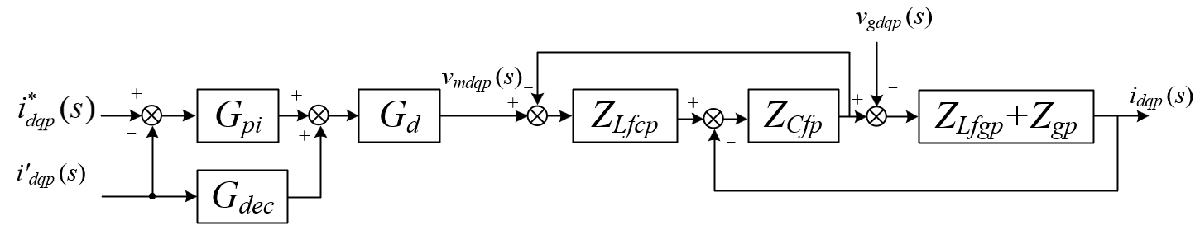


$$% MathType!MTEF!2!1!+-
% feaahqart1ev3aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBaerbd9wDYLwzYbItLDharqqtubsr
% 4rNCHbWexLMBbXgBd9gzLbvyNv2CaeHbl7mZLdGeaGqipu0Je9sqqr
% pepC0xbbL8F4rqqrFfpeea0xe9Lq-Jc9vqaqpepm0xbba9pwe9Q8fs
% 0-yqaqpepae9pg0FirpepeKkFr0xfr-xfr-xb9adbaqaaeGaciGaai
% aabeqaamaabaabauaakeGabaabuabaaaaaaaaapeGaamyAa8aadaWg
% aaWcbaWdbiaadsgacaWGXbGaamiCaaWdaeqaaOWdbiabg2da9maaya
% aapaqaa8qacqGHsisldaWadaWdaeaapeGaamOwa8aadaWgaaWcbaWd
% biaadYeacaWGMbGaam4yaiaadchaa8aabeaak8qacaWGAbWdamaaDa
% aaleaapeGaam4qaiaadAgacaWGWbaapaqaa8qacqGHsislcaaIXaaa
% aOWaaeWaa8aabaWdbiaadQfapaWaaSbaaSqaa8qacaWGmbGaamOzai
% aadEgacaWGWbaapaqabaGcpeGaey4kaSIaamOwa8aadaWgaaWcbaWd
% biaadEgacaWGWbaapaqabaaak8qacaGLOaGaayzkaaGaey4kaSIaam
% Owa8aadaWgaaWcbaWdbiaadYeacaWGMbGaam4yaiaadchaa8aabeaa
% k8qacqGHRaWkcaWGAbWdamaaBaaaleaapeGaamitaiaadAgacaWGNb
% GaamiCaaWdaeqaaOWdbiabgUcaRiaadQfapaWaaSbaaSqaa8qacaWG
% NbGaamiCaaWdaeqaaaGcpeGaay5waiaaw2faa8aadaahaaWcbeqaa8
% qacqGHsislcaaIXaaaaaWdaeaapeGaam4ra8aadaWgaaadbaWdbiaa
% igdacaWGWbaapaqabaaak8qacaGL44pacaWG2bWdamaaBaaaleaape
% GaamyBaiaadsgacaWGXbGaamiCaaWdaeqaaOWdbmaayaaapaqaa8qa
% cqGHsisldaWadaWdaeaapeWaaeWaa8aabaWdbiaadQfapaWaaSbaaS
% qaa8qacaWGmbGaamOzaiaadEgacaWGWbaapaqabaGcpeGaey4kaSIa
% amOwa8aadaWgaaWcbaWdbiaadEgacaWGWbaapaqabaaak8qacaGLOa
% GaayzkaaWaaeWaa8aabaWdbiaadQfapaWaa0baaSqaa8qacaWGdbGa
% amOzaiaadchaa8aabaWdbiabgkHiTiaaigdaaaGccqGHsislcaWGAb
% WdamaaDaaaleaapeGaamitaiaadAgacaWGJbGaamiCaaWdaeaapeGa
% eyOeI0IaaGymaaaaaOGaayjkaiaawMcaamaabmaapaqaa8qacaWGAb
% WdamaaBaaaleaapeGaamitaiaadAgacaWGNbGaamiCaaWdaeqaaOWd
% biabgUcaRiaadQfapaWaaSbaaSqaa8qacaWGNbGaamiCaaWdaeqaaa
% GcpeGaayjkaiaawMcaaaGaay5waiaaw2faa8aadaahaaWcbeqaa8qa
% cqGHsislcaaIXaaaaaWdaeaapeGaam4ra8aadaWgaaadbaWdbiaadI
% hacaWGWbaapaqabaaak8qacaGL44pacaWG2bWdamaaBaaaleaapeGa
% am4zaiaadsgacaWGXbGaamiCaaWdaeqaaaaa!AC37!
\[{i_{dqp}} = \underbrace {  {{\left[ {{Z_{Lfcp}}Z_{Cfp}^{ - 1}\left( {{Z_{Lfgp}} + {Z_{gp}}} \right) + {Z_{Lfcp}} + {Z_{Lfgp}} + {Z_{gp}}} \right]}^{ - 1}}}_{{G_1}}{v_{mdqp}}\underbrace { - {{\left[ {\left( {{Z_{Lfgp}} + {Z_{gp}}} \right)\left( {Z_{Cfp}^{ - 1} - Z_{Lfcp}^{ - 1}} \right)\left( {{Z_{Lfgp}} + {Z_{gp}}} \right)} \right]}^{ - 1}}}_{{G_{x1}}}{v_{gdqp}}\]$$


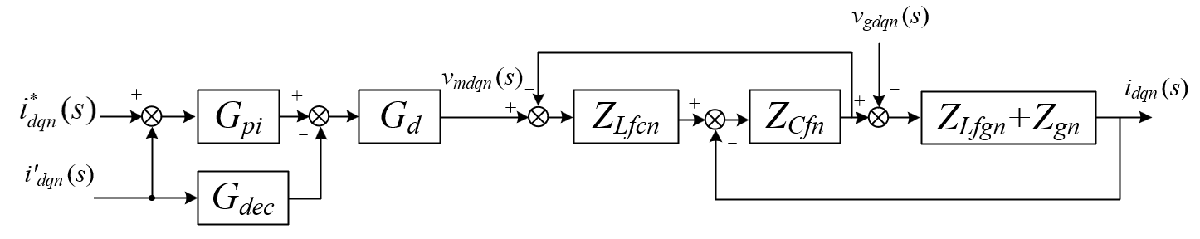

$\[{i_{dqn}} = \underbrace { {{\left[ {{Z_{Lfcn}}Z_{Cfn}^{ - 1}\left( {{Z_{Lfgn}} + {Z_{gn}}} \right) + {Z_{Lfcn}} + {Z_{Lfgn}} + {Z_{gn}}} \right]}^{ - 1}}}_{{G_2}}{v_{mdqn}}\underbrace { - {{\left[ {\left( {{Z_{Lfgn}} + {Z_{gn}}} \right)\left( {Z_{Cfn}^{ - 1} - Z_{Lfcn}^{ - 1}} \right)\left( {{Z_{Lfgn}} + {Z_{gn}}} \right)} \right]}^{ - 1}}}_{{G_{x2}}}{v_{gdqn}}\]$（1）

%% vmdqp to idqp
G00  = Z_Lfcp*Z_Cfp_inv*(Z_Lfgp+Z_gp)+Z_Lfcp+Z_Lfgp+Z_gp;
G00 = minreal(G00);
G1 = inv(G00);
G1_ss=ss(G1);
G1 = tf(minreal(G1_ss));

18 states removed.


%% vmdqn to idqn
G01  = Z_Lfcn*Z_Cfn_inv*(Z_Lfgn+Z_gn)+Z_Lfcn+Z_Lfgn+Z_gn;
G2 = inv(G01);
G2_ss=ss(G2);
G2 = tf(minreal(G2_ss));

18 states removed.


$\[{v_{mdqp}} = {G_d}{G_{pi}}i_{dqp}^ *  + {G_d}\left( {{G_{dec}} - {G_{pi}}} \right){i'_{dqp}}\]$（2）


$$\[{v_{mdqn}} = {G_d}{G_{pi}}i_{dqn}^ *  - {G_d}\left( {{G_{dec}} + {G_{pi}}} \right){i'_{dqn}}\]$$


将式（2）代入式（1），得到i_dqp关于i_dqp* 和v_gdqp的表达式

$\[{i_{dqp}} = {G_1}{G_d}{G_{pi}}i_{dqp}^ *  + \underbrace {{G_1}{G_d}\left( {{G_{dec}} - {G_{pi}}} \right)}_{{G_{3p}}}{i'_{dqp}} + {G_{x1}}{v_{gdqp}}\]$（3）

与i_dqn关于i_dqn*和v_gdqn的表达式


$$\[{i_{dqn}} = {G_2}{G_d}{G_{pi}}i_{dqn}^ *  \underbrace {- {G_2}{G_d}\left( {{G_{dec}} + {G_{pi}}} \right)}_{{G_{3n}}}{i'_{dqn}} + {G_{x2}}{v_{gdqn}}\]$$


接下来忽略电网电压

现需求出控制部分的电流idqp_prime与真实电流idqp的关系。

可以看到，正负电流的耦合

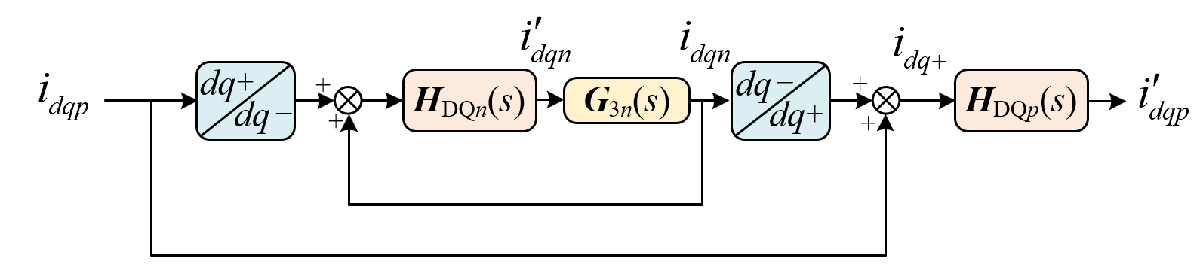

G3_ss = -minreal(ss(G2*G_delay_pade))*minreal(ss((G_pi+G_decouple)));

6 states removed.


% G3 = -G_delay_pade*G2*(G_pi+G_dec);
% G3_ss = ss(G3);
G3n = tf(minreal(G3_ss));
% G4n是这个小闭环的传递函数
HDQ_n_ss = ss(HDQ_n);
G4_ss_open = HDQ_n_ss*G3_ss;
G4_ss_open = minreal(G4_ss_open);

4 states removed.


I = eye(2);  % 2x2 单位矩阵
G4n = feedback(G4_ss_open, I, +1);  % +1 表示正反馈
G4n = tf(minreal(G4n));

对G4n做频移后实部虚部分离，可以得到


$$% MathType!MTEF!2!1!+-
% feaahqart1ev3aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBaerbd9wDYLwzYbItLDharqqtubsr
% 4rNCHbWexLMBbXgBd9gzLbvyNv2CaeHbl7mZLdGeaGqipu0Je9sqqr
% pepC0xbbL8F4rqqrFfpeea0xe9Lq-Jc9vqaqpepm0xbba9pwe9Q8fs
% 0-yqaqpepae9pg0FirpepeKkFr0xfr-xfr-xb9adbaqaaeGaciGaai
% aabeqaamaabaabauaakqGaeeqaaqafbaacbmGab8xAayaafaWaaSba
% aSqaaiaadsgacaWGXbGaamiCaaqabaGccqGH9aqpcaWFibWaaSbaaS
% qaaiaadseacaWGrbGaamiCaaqabaGccaGGOaGaam4CaiaacMcadaqa
% daqaamaaeiaabaWaamWaaeaacaWFhbWaaSbaaSqaaiaaisdacaWGUb
% aabeaakiaacIcacaWGZbGaaiykamaabmaabaWaaqGaaeaacaWFPbWa
% aSbaaSqaaiaadsgacaWGXbGaamiCaaqabaGccaGGOaGaam4CaiaacM
% caaiaawIa7amaaBaaaleaacaWGZbGaeyypa0Jaam4CaiabgkHiTiaa
% dQgacaaIYaGaeqyYdC3aaSbaaWqaaiaaicdaaeqaaaWcbeaaaOGaay
% jkaiaawMcaaaGaay5waiaaw2faaaGaayjcSdWaaSbaaSqaaiaadoha
% cqGH9aqpcaWGZbGaey4kaSIaamOAaiaaikdacqaHjpWDdaWgaaadba
% GaaGimaaqabaaaleqaaOGaey4kaSIaa8xsaiaa-LgadaWgaaWcbaGa
% amizaiaadghacaWGWbaabeaakiaacIcacaWGZbGaaiykaaGaayjkai
% aawMcaaaqaaiabg2da9maayaaabaGaa8hsamaaBaaaleaacaWGebGa
% amyuaiaadchaaeqaaOGaaiikaiaadohacaGGPaWaaeWaaeaacaWFhb
% WaaSbaaSqaaiaaisdacaWGUbaabeaakiaacIcacaWGZbGaey4kaSIa
% amOAaiaaikdacqaHjpWDdaWgaaWcbaGaaGimaaqabaGccaGGPaGaey
% 4kaSIaa8xsaaGaayjkaiaawMcaaaWcbaGaa8hsamaaBaaameaacaWG
% WbaabeaaaOGaayjo+dGaa8xAamaaBaaaleaacaWGKbGaamyCaiaadc
% haaeqaaOGaaiikaiaadohacaGGPaaaaaa!9513!
\[\begin{array}{c}
{{i'}_{dqp}} = {H_{DQp}}(s)\left( {{{\left. {\left[ {{G_{4n}}(s)\left( {{{\left. {{i_{dqp}}(s)} \right|}_{s = s - j2{\omega _0}}}} \right)} \right]} \right|}_{s = s + j2{\omega _0}}} + I{i_{dqp}}(s)} \right)\\
 = \underbrace {{H_{DQp}}(s)\left( {{G_{4n}}(s + j2{\omega _0}) + I} \right)}_{{H_p}}{i_{dqp}}(s)
\end{array}\]$$


% 分离后得到的实矩阵，称之为G5
G4_11 = G4n(1,1);
G4_12 = G4n(1,2);

num_tfG4_11 = G4_11.Numerator{1};
den_tfG4_11 = G4_11.Denominator{1};
num_tfG4_12 = G4_12.Numerator{1};
den_tfG4_12 = G4_12.Denominator{1};
syms s real
% 化简后转换为符号表达式
G4_11_sym = poly2sym(num_tfG4_11, s) / poly2sym(den_tfG4_11, s);
G4_11_replaced = subs(G4_11_sym, s, s + 1i*2*100*pi);
% 分离实部和虚部
G4_11_replaced = collect(G4_11_replaced);
G4_11_real = real(G4_11_replaced);
G4_11_imag = imag(G4_11_replaced);
G4_11_real = collect(G4_11_real);
[num_G4_11_real, den_G4_11_real] = numden(G4_11_real);
num_G4_11_real = sym2poly(num_G4_11_real);
den_G4_11_real = sym2poly(den_G4_11_real);
G4_11_real_tf = tf(num_G4_11_real, den_G4_11_real);
G4_11_real_tf = minreal(G4_11_real_tf);
[num_G4_11_imag, den_G4_11_imag] = numden(G4_11_imag);
num_G4_11_imag = sym2poly(num_G4_11_imag);
den_G4_11_imag = sym2poly(den_G4_11_imag);
G4_11_imag_tf = tf(num_G4_11_imag, den_G4_11_imag);
G4_11_imag_tf = minreal(G4_11_imag_tf);


G4_12_sym = poly2sym(num_tfG4_12, s) / poly2sym(den_tfG4_12, s);
G4_12_replaced = subs(G4_12_sym, s, s + 1i*2*100*pi);
% 分离实部和虚部
G4_12_replaced = collect(G4_12_replaced);
G4_12_real = real(G4_12_replaced);
G4_12_imag = imag(G4_12_replaced);
G4_12_real = collect(G4_12_real);
[num_G4_12_real, den_G4_12_real] = numden(G4_12_real);
num_G4_12_real = sym2poly(num_G4_12_real);
den_G4_12_real = sym2poly(den_G4_12_real);
G4_12_real_tf = tf(num_G4_12_real, den_G4_12_real);
G4_12_real_tf = minreal(G4_12_real_tf);
[num_G4_12_imag, den_G4_12_imag] = numden(G4_12_imag);
num_G4_12_imag = sym2poly(num_G4_12_imag);
den_G4_12_imag = sym2poly(den_G4_12_imag);
G4_12_imag_tf = tf(num_G4_12_imag, den_G4_12_imag);
G4_12_imag_tf = minreal(G4_12_imag_tf);


G11real_ss = ss(G4_11_real_tf);
G12imag_ss = ss(G4_12_imag_tf);
G5_11_ss = G11real_ss + G12imag_ss;
G5_11 = tf(minreal(G5_11_ss));

48 states removed.


G5_22 = G5_11;
G11imag_ss = ss(G4_11_imag_tf);
G12real_ss = ss(G4_12_real_tf);
G5_12_ss = -G11imag_ss + G12real_ss;
G5_12 = tf(minreal(G5_12_ss));

48 states removed.


G5_21 = -G5_12;
G5 = [G5_11, G5_12;
      G5_21, G5_22];

HDQ_p_ss = ss(HDQ_p);
G5_ss = ss(G5);
I = eye(size(G5));        % 单位传递函数矩阵
I_tf = tf(I);             % 转为传递函数对象
I_ss = ss(I_tf);          % 再转为状态空间
Sum_ss = I_ss + G5_ss;        % I + G5
Hp_ss = HDQ_p_ss * Sum_ss;  % H_p * (I + G5)
Hp = tf(minreal(Hp_ss));

56 states removed.


可以得到正序电流参考到正序电流的表达式：


$$\[{i_{dqp}} = \underbrace {{{\left( {I - {G_1}{G_d}\left( {{G_{dec}} - {G_{pi}}} \right){H_p}} \right)}^{ - 1}}{G_1}{G_d}{G_{pi}}}_{{T_p}}i_{dqp}^ * \]$$


G_pi_ss   = ss(G_pi);
G_dec_ss = ss(G_decouple);
G1_ss = ss(G1);
Hp_ss = ss(Hp);

A_ss = I_ss-G1_ss*G_delay_pade*(G_dec_ss-G_pi_ss)*Hp_ss;
B_ss = G1_ss*G_delay_pade*G_pi_ss;
A_ss = minreal(A_ss);

28 states removed.


B_ss = minreal(B_ss);

6 states removed.


Tp_ss = A_ss\B_ss;
Tp = tf(minreal(Tp_ss));

8 states removed.


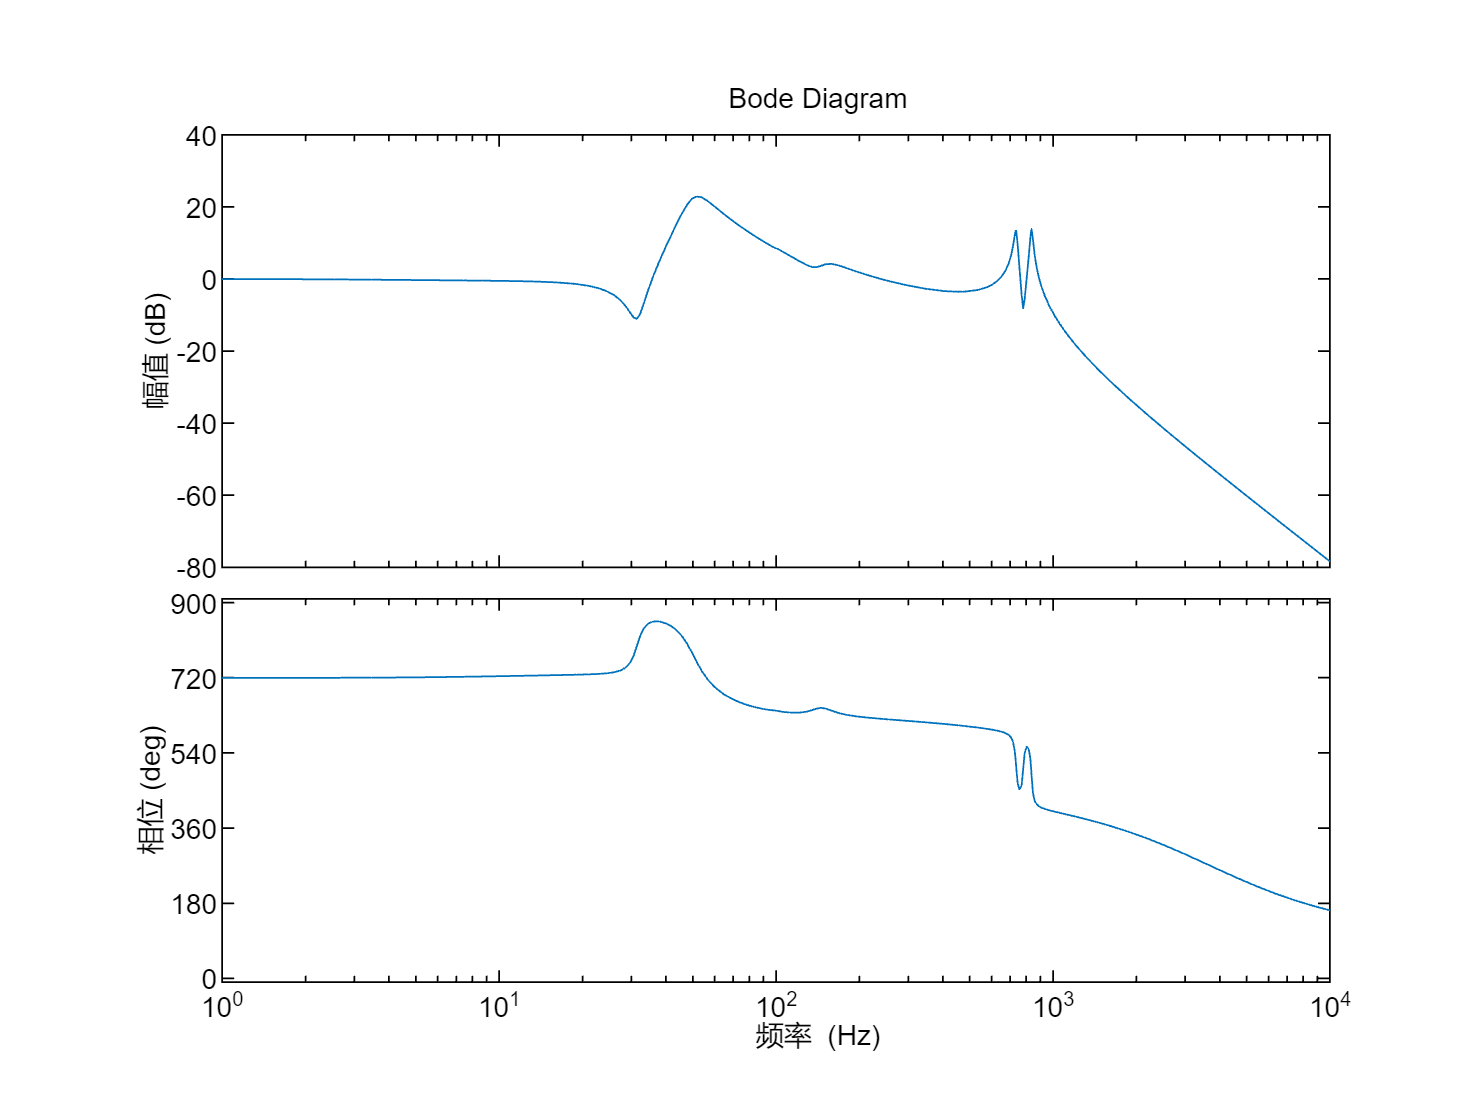

is_stable = logical
   1


Tp_11 = Tp(1,1);
Tp_12 = Tp(1,2);
% save('Tp_11.mat', 'Tp_11');
% save('Tp_12.mat', 'Tp_12');
% save('G4n.mat', 'G4n');
opt=bodeoptions;
opt.FreqUnits = 'Hz';
opt.XLim = [1,1e4];
bode(Tp(1,1),opt);is_stable = isstable(Tp_11)

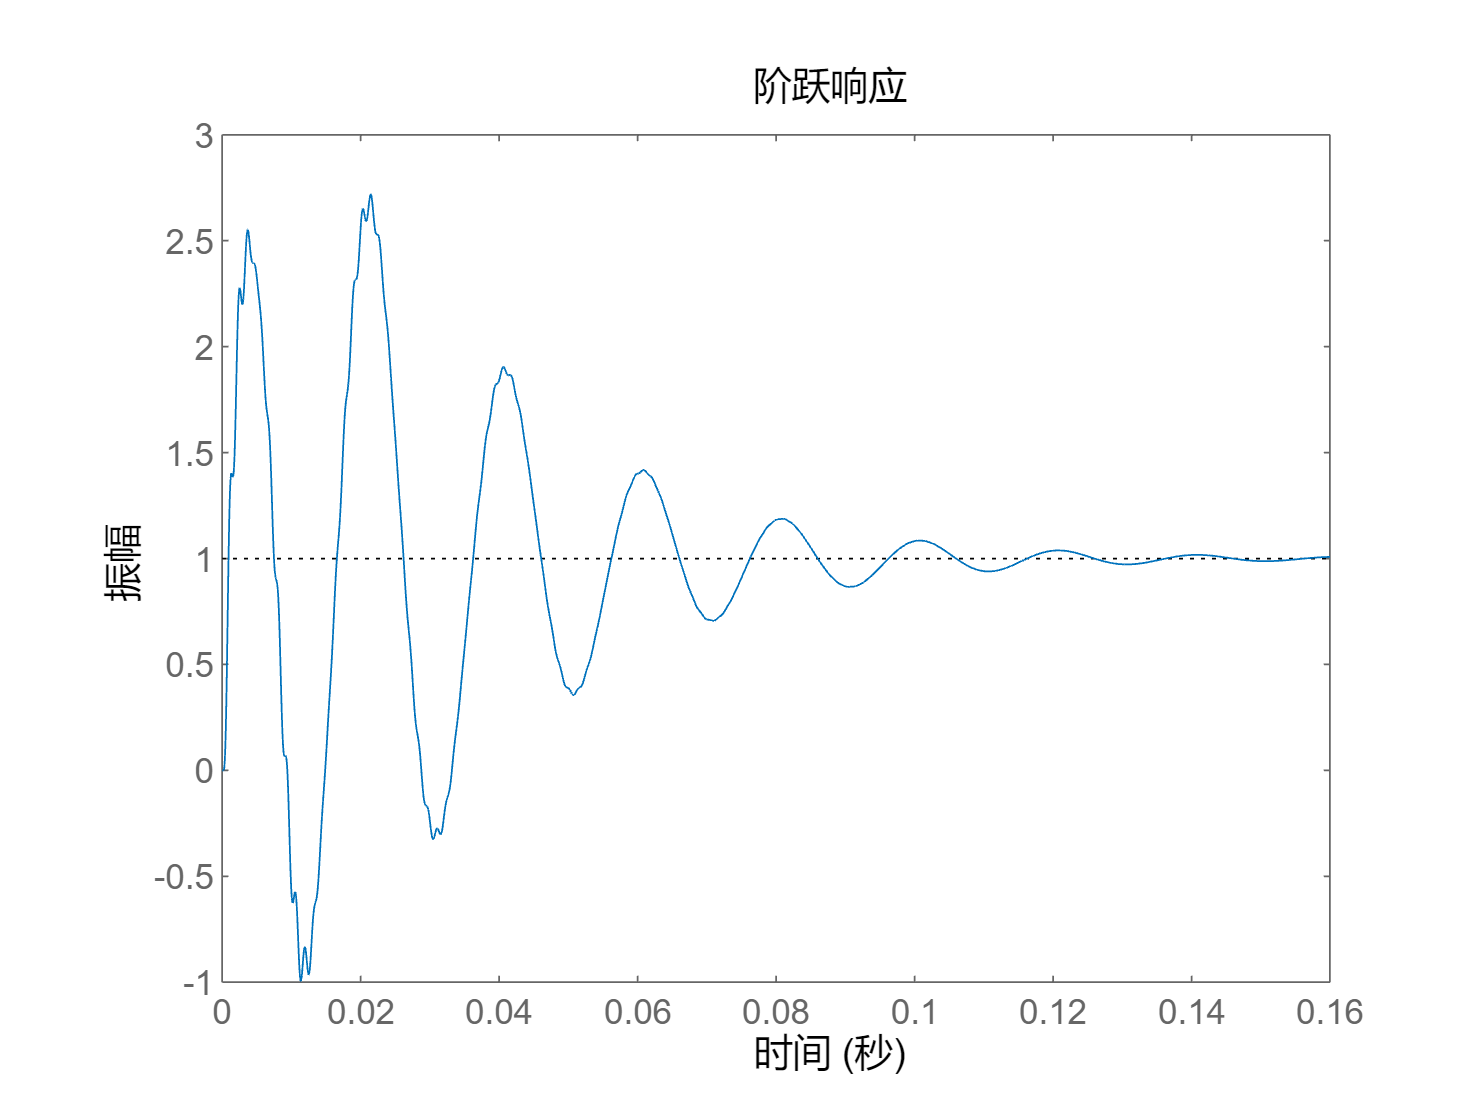

% damp(Tp(1,1));
% nyquist(Tp_11);
step(Tp_11);

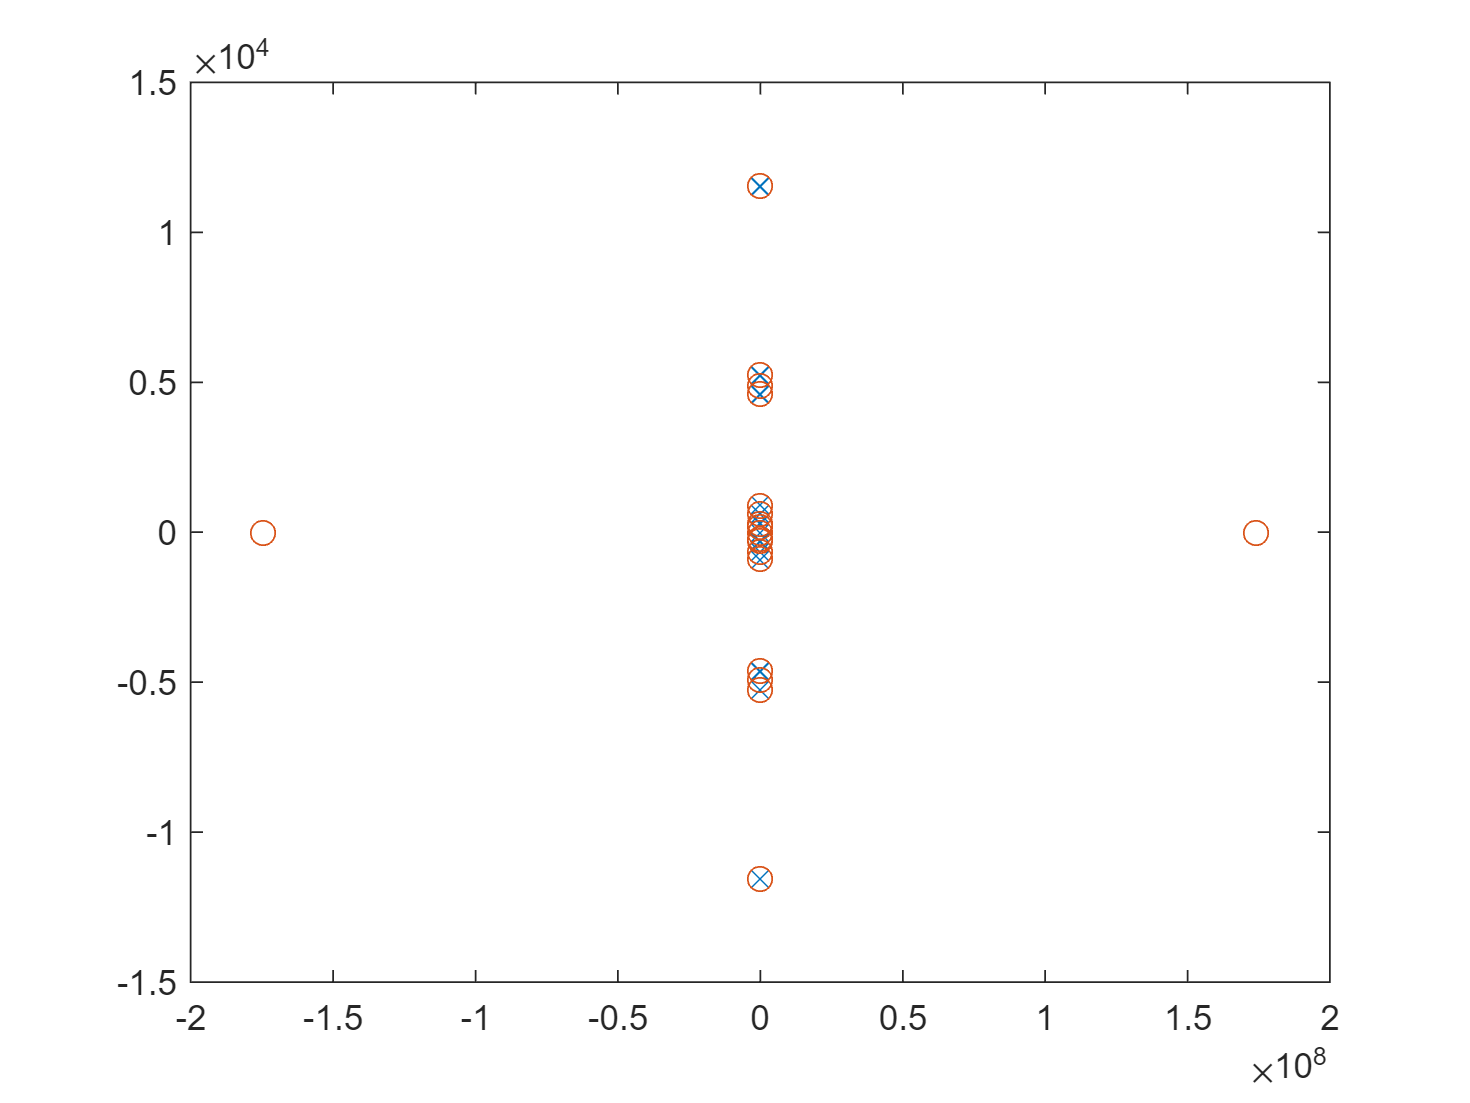

poles_Tp = pole(Tp_11);
zeros_Tp = zero(Tp_11);
figure;
plot(real(poles_Tp), imag(poles_Tp), 'x', 'MarkerSize', 7);
hold on;
plot(real(zeros_Tp), imag(zeros_Tp), 'o', 'MarkerSize', 7);